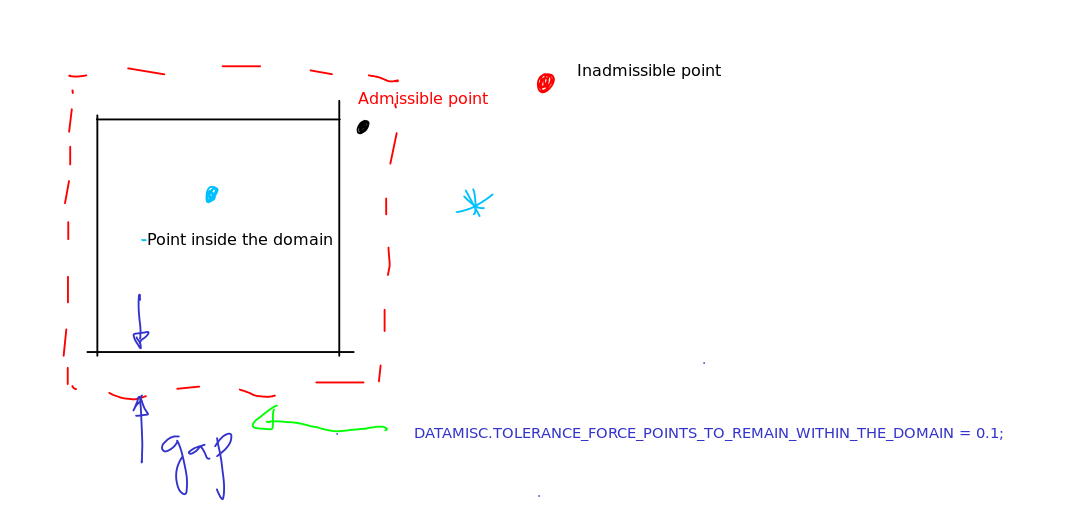

POINTS_INSIDE_DOMAIN = ones(m,1) ;

for idim = 1:ndim
    POINTS_INSIDE_DOMAIN = POINTS_INSIDE_DOMAIN.*(xNEW(:,idim) >= DATALOC.xLIM(idim,1)).*(xNEW(:,idim) <= DATALOC.xLIM(idim,2)) ;
end

xLIM_EXPANDED = zeros(size(DATALOC.xLIM)) ; 

GAP_OVER_1 = DATALOC.TOLERANCE_FORCE_POINTS_TO_REMAIN_WITHIN_THE_DOMAIN; 

xLIM_EXPANDED(:,1)= DATALOC.xLIM(:,1) -  GAP_OVER_1*(DATALOC.xLIM(:,2)-DATALOC.xLIM(:,1)) ; 
xLIM_EXPANDED(:,2)= DATALOC.xLIM(:,2) +  GAP_OVER_1*(DATALOC.xLIM(:,2)-DATALOC.xLIM(:,1)) ; 

ADMISSIBLE_POINTS = ones(m,1) ;

for idim = 1:ndim
    ADMISSIBLE_POINTS = ADMISSIBLE_POINTS.*(xNEW(:,idim) >= xLIM_EXPANDED(idim,1)).*(xNEW(:,idim) <= xLIM_EXPANDED(idim,2)) ;
end